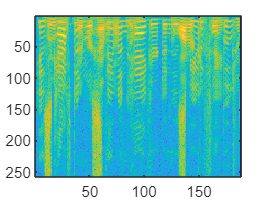

shortfft = shortfft(:,:,1) =

   0.0369 - 0.0001i   0.0334 + 0.0001i   0.0359 + 0.0001i   0.0254 - 0.0002i   0.0187 + 0.0002i  -0.0001 - 0.0002i   0.0036 - 0.0003i  -0.0060 + 0.0002i  -0.0091 + 0.0002i  -0.0082 - 0.0002i   0.0030 - 0.0001i  -0.0081 + 0.0001i  -0.0175 + 0.0003i  -0.0138 - 0.0001i  -0.0159 - 0.0002i   0.0076 - 0.0001i   0.0025 + 0.0000i  -0.0100 + 0.0006i  -0.1050 - 0.0017i   0.1092 + 0.0020i  -0.0327 - 0.0005i  -0.0143 - 0.0002i  -0.0123 + 0.0001i  -0.0077 + 0.0003i  -0.0138 + 0.0002i  -0.0263 - 0.0003i  -0.0048 - 0.0003i  -0.0179 - 0.0002i   0.0424 + 0.0010i  -0.0162 - 0.0007i  -0.0033 + 0.0001i   0.0057 + 0.0000i   0.0289 - 0.0001i   0.0142 + 0.0001i   0.0130 + 0.0001i  -0.0003 - 0.0004i   0.0240 + 0.0002i   0.0055 + 0.0003i  -0.0195 + 0.0000i   0.0041 - 0.0002i  -0.0021 + 0.0000i  -0.0265 + 0.0001i  -0.0146 - 0.0000i   0.0038 - 0.0002i  -0.0029 + 0.0000i  -0.0131 + 0.0001i   0.0110 - 0.0001i  -0.0111 + 0.0002i  -0.0100 - 0.0000i  -0.0119 - 0.0001i  -0.0133 - 0.0000i 

clc
clear all
load Observation_wb.mat

win = hann(512);%这个是给每一个短的宽带信号加窗
nfft = 512; %指的是每一个短的宽带信号里的采样点个数，由于它是对称的，所以后来取一半加1
inc = 256; %每次往前推进的长度
shortfft = zeros(nfft/2+1,fix(size(X,1)/inc)+1,size(X,2));%X是48000*4的矩阵（fix相当于是四舍五入，+1相当于是防止数据越界，数组里面多一个空格是没事的，但若少了一个空格数据放不下就有事了）;size(X,1)就是找出X的行数   size(X,2)就是找出X的列数
a = 0; 
for i = 0:inc:(size(X,1)-nfft);  %size(X,1)-nfft相当于是（48000-nfft）就是防止加窗溢出
    a = a+1;%即这个是在数组中遍历'短的宽带信号'，一共是有188个
    for j = 1:size(X,2); %相当于1：4 就是遍历4个麦克风
        w = win.*X(i+1:i+nfft,j);%w相当于是加完窗的数据
        t = fft(w,nfft);%t相当于是给加完窗的每一个短的宽带信号做fft变化得出的结果,nfft就是每一个短的宽带信号的结果
        shortfft(:,a,j) = t(1:nfft/2+1);%第j个麦克风，第a个间隔，把1-257个频率放进shortfft中
    end
end
imagesc((real(10*log10(shortfft(:,:,1)))));%画图，取log

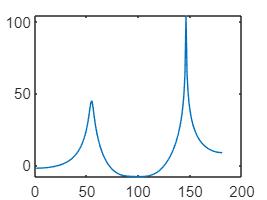

p_value = zeros(nfft/2+1,181);
for i = 1:(nfft/2+1)
    sfft = zeros(a,size(X,2));
    for j = 1:a
        for k = 1:4
            sfft(j,k) = shortfft(i,j,k);
        end
    end
    [c,b] = Pmusic_g(0.025,sfft,(i-1)/512*16000);
    for j = 1:181
      p_value(i,j) = 1./c(j);
    end
end
ans = zeros(181,1);
for i = 1:257
    ans(:,1) = ans(:,1) + p_value(i,:)';
end
ans = 257./ans;%1/P(theta)*257指的是先把分母上的P(theta)累加起来再取平均

plot(real(10*log(ans)));
p_value=ans;
theta = -90:1:90;    
n_source = 2;
P_middle = abs(p_value(2:end-1));
P_front = abs(p_value(1:end-2));
P_back = abs(p_value(3:end));
logic_front = (P_middle - P_front)>0;
logic_back = (P_middle - P_back)>0;
logic = logic_front & logic_back;
P_middle(~logic) = min(P_middle);
P_local = [abs(p_value(1));P_middle;abs(p_value(end))];
[~,doa_Idx] = maxk(P_local,n_source);
doa = theta(doa_Idx);
[~,minIdx] = min(abs(doa));
doa_source = doa(minIdx);
[~,maxIdx] = max(abs(doa));
interfer = doa(maxIdx);
disp(['The desired source DOA with MUSIC is: ',num2str(doa_source),' deg']);

The desired source DOA with MUSIC is: -36 deg


disp(['The interfering DOA with MUSIC is: ',num2str(interfer),' deg']);

The interfering DOA with MUSIC is: 55 deg
